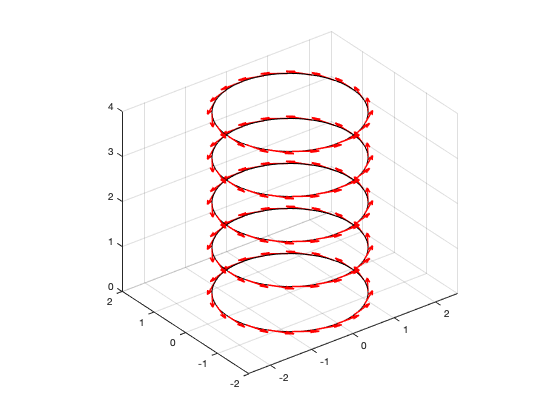

%% PASO 1: CARACTERÍSTICAS DE LA ESPIRA
nL = 5;          % Número de espiras: número total de vueltas del alambre conductor

N = 20;          % Puntos por espira: discretización de cada espira para aproximar la integral
R = 1.5;         % Radio de cada espira (m): radio de la trayectoria circular de la corriente
sz = 1;          % Separación entre espiras (paso en Z, m): distancia entre cada vuelta, define una hélice
I = 300;         % Corriente (A): corriente que circula por las espiras, fuente del campo magnético
mu0 = 4*pi*1e-7; % Permeabilidad magnética del vacío: constante física que relaciona campo magnético con corriente
km = mu0 * I / (4*pi); % Constante de Biot-Savart: factor multiplicativo que aparece en la ley de Biot-Savart
rw = 0.2;        % Grosor efectivo del alambre: usado para visualización o cálculos de campo si se considera espesor

%% PASO 2: Definir el vector de ángulos
theta = linspace(0, 2*pi, N+1); % Ángulos de 0 a 2π: divide la espira en N segmentos
theta = theta(1:end-1); % Se elimina el último punto para evitar duplicación (0 y 2π son el mismo punto)

%% Inicialización de vectores para almacenar coordenadas y dl
x_total = [];
y_total = [];
z_total = [];
dlx_total = [];
dly_total = [];

%% PASO 5: Ciclo para cada espira
for k = 1:nL
    % PASO 4: Calcular posiciones y dl para esta espira
    z = (k-1)*sz; % Altura z de esta espira: al avanzar en k, se forma una hélice de varias espiras
    
    % Coordenadas de los puntos en la espira
    x = R * cos(theta); % Coordenadas x: define una circunferencia en el plano XY
    y = R * sin(theta); % Coordenadas y: junto con x forman el círculo
    
    % Componentes del diferencial de línea (dl)
    dlx = -R * sin(theta) * (theta(2)-theta(1)); % dx: componente diferencial en x (dirección tangente a la espira)
    dly = R * cos(theta) * (theta(2)-theta(1));  % dy: componente diferencial en y (también tangente)
    % Estos diferenciales representan un pequeño vector tangente al alambre, necesarios para Biot-Savart
    
    % Almacenar en vectores totales
    x_total = [x_total, x]; % Coordenadas x acumuladas para todas las espiras
    y_total = [y_total, y]; % Coordenadas y acumuladas
    z_total = [z_total, z*ones(1,N)]; % z constante en cada espira, pero cambia con k
    dlx_total = [dlx_total, dlx]; % Componentes x del vector diferencial dl
    dly_total = [dly_total, dly]; % Componentes y del vector diferencial dl
end

%% Visualización
figure(1);
hold on;
axis equal;
grid on;
xlabel('X (m)');  % X (m)
ylabel('Y (m)');  % Y (m)
zlabel('Z (m)');  % Z (m)
title('Vectores diferenciales de línea (dl) en espiras');   % Vectores diferenciales de línea (dl) en espiras

% Dibujar las espiras
for k = 1:nL
    z = (k-1)*sz;
    plot3(R*cos(linspace(0,2*pi,100)), R*sin(linspace(0,2*pi,100)), z*ones(1,100), 'k-');
    % Se grafica cada espira como una línea circular en el plano XY a una altura z fija
end

% Dibujar los vectores dl usando quiver
quiver3(x_total, y_total, z_total, dlx_total, dly_total, zeros(size(dlx_total)), 'r', 'LineWidth', 1.5);
% Se grafican los vectores diferenciales de línea dl en cada punto, en rojo
% Estos vectores son esenciales en la Ley de Biot-Savart para calcular el campo magnético

view(3); % Vista 3D para apreciar la geometría espacial de la espira
